%Specify result file route and name
fileNames = ["C:\Users\irene\Desktop\results1", "C:\Users\irene\Desktop\results2", "C:\Users\irene\Desktop\results3","C:\Users\irene\Desktop\results4"];
names_of_experiments = {'1','2','3','4'};

% Initialize a cell array to store the JSON data
jsonData = cell(numel(fileNames), 1);
% Read the JSON files
for i = 1:numel(fileNames)
    fileName = fileNames{i};
    fileID = fopen(fileName, 'r');
    jsonData{i} = jsondecode(fread(fileID, inf, 'char=>char')');
    fclose(fileID);
end
%%Create directory to store graphs
mkdir('Results_Charts/');

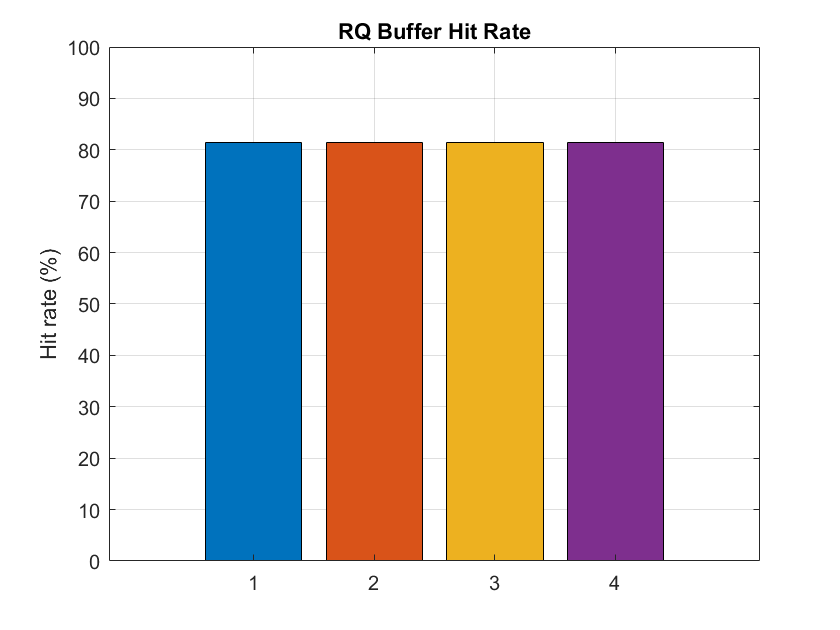

%Plot #1 : Hit Ratio DRAM Buffer
hits = zeros(numel(fileNames),1);
miss = zeros(numel(fileNames),1);
hitrate = zeros(numel(fileNames),1);
for i = 1:numel(fileNames)
    hits(i,1)=jsonData{i,1}.roi.DRAM.RQROW_BUFFER_HIT;
    miss(i,1)=jsonData{i,1}.roi.DRAM.RQROW_BUFFER_MISS;
    hitrate(i,1)= 100 * (hits(i,1)/(miss(i,1)+hits(i,1)));
end

% Create a bar plot with custom colors
barHandle = bar(diag(hitrate), 'stacked');

% Customize the plot (optional)
ylim([0, 100]);
title('RQ Buffer Hit Rate');
ylabel('Hit rate (%)');
set(gca, 'XTickLabel', names_of_experiments); % Set x-axis labels
grid on;
saveas(gcf, 'Results_Charts/RQ Buffer Hit Rate.pdf');

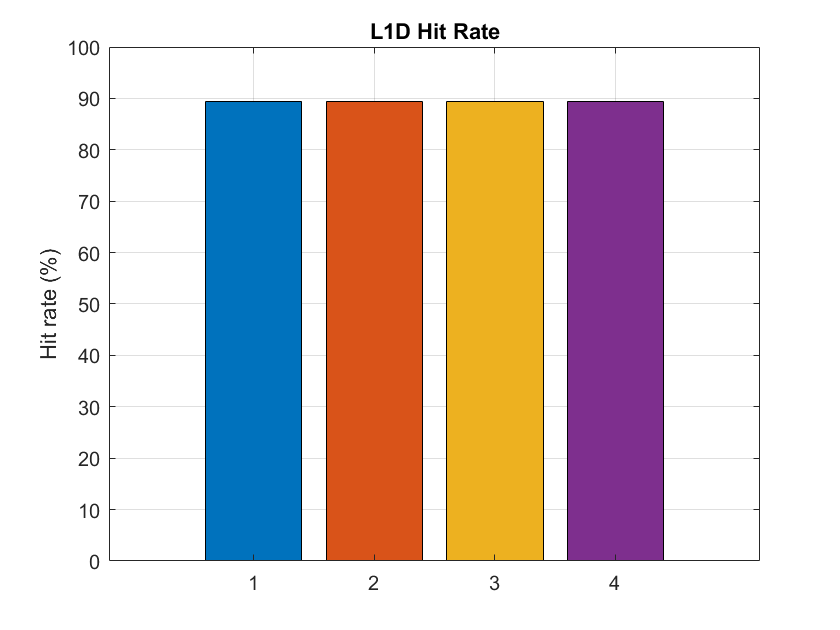

%Plot #2 Hit ratio L1D 
hits = zeros(numel(fileNames),1);
miss = zeros(numel(fileNames),1);
hitrate = zeros(numel(fileNames),1);
for i = 1:numel(fileNames)
    hits(i,1)=jsonData{i,1}.roi.cpu0_L1D.LOAD.hit +jsonData{i,1}.roi.cpu0_L1D.PREFETCH.hit +jsonData{i,1}.roi.cpu0_L1D.RFO.hit + jsonData{i,1}.roi.cpu0_L1D.TRANSLATION.hit + jsonData{i,1}.roi.cpu0_L1D.WRITE.hit;
    miss(i,1)=jsonData{i,1}.roi.cpu0_L1D.LOAD.miss +jsonData{i,1}.roi.cpu0_L1D.PREFETCH.miss +jsonData{i,1}.roi.cpu0_L1D.RFO.miss + jsonData{i,1}.roi.cpu0_L1D.TRANSLATION.miss + jsonData{i,1}.roi.cpu0_L1D.WRITE.miss;
    hitrate(i,1)= 100 * (hits(i,1)/(miss(i,1)+hits(i,1)));
end

% Create a bar plot with custom colors
barHandle = bar(diag(hitrate), 'stacked');

% Customize the plot (optional)
ylim([0, 100]);
title('L1D Hit Rate');
ylabel('Hit rate (%)');
set(gca, 'XTickLabel', names_of_experiments); % Set x-axis labels
grid on;
saveas(gcf, 'Results_Charts/L1D Hit Rate.pdf');

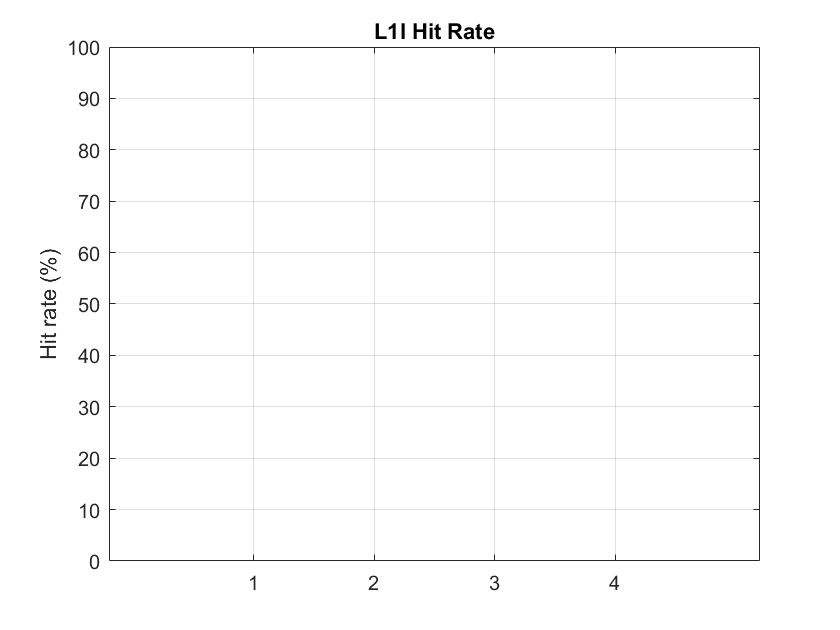

%Plot #3 Hit ratio L1I
hits = zeros(numel(fileNames),1);
miss = zeros(numel(fileNames),1);
hitrate = zeros(numel(fileNames),1);
for i = 1:numel(fileNames)
    hits(i,1)=jsonData{i,1}.roi.cpu0_L1I.LOAD.hit +jsonData{i,1}.roi.cpu0_L1I.PREFETCH.hit +jsonData{i,1}.roi.cpu0_L1I.RFO.hit + jsonData{i,1}.roi.cpu0_L1I.TRANSLATION.hit + jsonData{i,1}.roi.cpu0_L1I.WRITE.hit;
    miss(i,1)=jsonData{i,1}.roi.cpu0_L1I.LOAD.miss +jsonData{i,1}.roi.cpu0_L1I.PREFETCH.miss +jsonData{i,1}.roi.cpu0_L1I.RFO.miss + jsonData{i,1}.roi.cpu0_L1I.TRANSLATION.miss + jsonData{i,1}.roi.cpu0_L1I.WRITE.miss;
    hitrate(i,1)= 100 * (hits(i,1)/(miss(i,1)+hits(i,1)));
end

% Create a bar plot with custom colors
barHandle = bar(diag(hitrate), 'stacked');

% Customize the plot (optional)
ylim([0, 100]);
title('L1I Hit Rate');
ylabel('Hit rate (%)');
set(gca, 'XTickLabel', names_of_experiments); % Set x-axis labels
grid on;
saveas(gcf, 'Results_Charts/L1I Hit Rate.pdf');

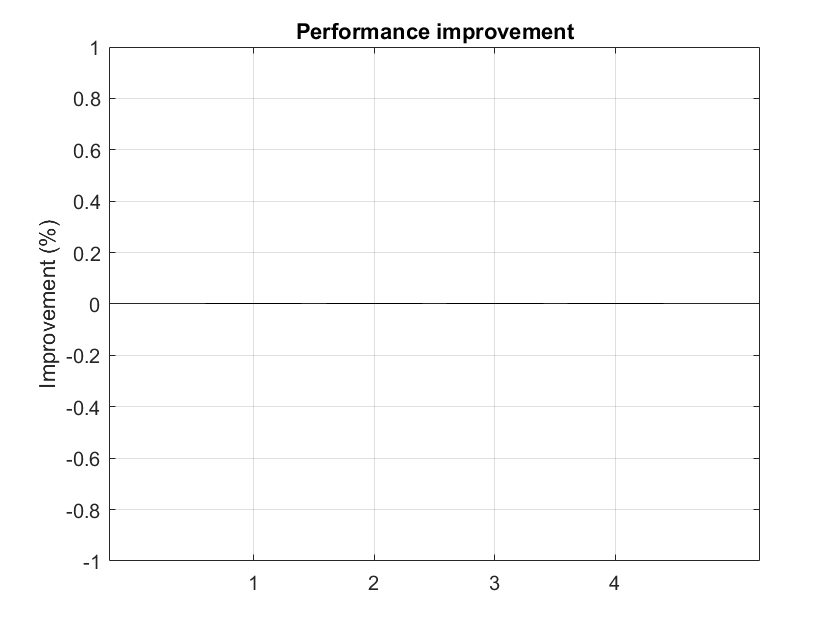

%Plot #4 Performance improvement
%Here im doing it based on the hitrate of dram but it can be done with any
%parameter, I'm also asuming that the experiment 1 is the one with no
%prefetcher
hits = zeros(numel(fileNames),1);
miss = zeros(numel(fileNames),1);
hitrate = zeros(numel(fileNames),1);
for i = 1:numel(fileNames)
    hits(i,1)=jsonData{i,1}.roi.DRAM.RQROW_BUFFER_HIT;
    miss(i,1)=jsonData{i,1}.roi.DRAM.RQROW_BUFFER_MISS;
    hitrate(i,1)= 100 * (hits(i,1)/(miss(i,1)+hits(i,1)));
end

perf_improvement = zeros(numel(fileNames),1);
for i = 2:numel(fileNames)
    perf_improvement(i,1)=hitrate(i,1) - hitrate(1,1);
end
% Create a bar plot with custom colors
barHandle = bar(diag(perf_improvement), 'stacked');

% Customize the plot (optional)
title('Performance improvement');
ylabel('Improvement (%)');
set(gca, 'XTickLabel', names_of_experiments); % Set x-axis labels
grid on;
saveas(gcf, 'Results_Charts/Performance improvement.pdf');